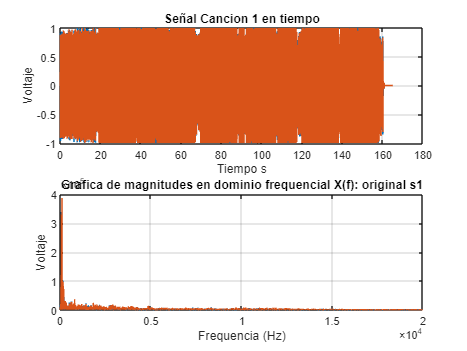

%1) Definir señal de mensaje para cancion 1 2 y 3
% definición de la señal de audio por ruta relativa: cancion 1
[audio, fs] = audioread('cancion1.wav');

% definición de la señal de audio por ruta relativa: cancion 2
[audio2, fs2] = audioread('cancion2.wav');

% definición de la señal de audio por ruta relativa: cancion 3
[audio3, fs3] = audioread('cancion3.wav');

% transformada de fourier sobre la señal de audio 1
fft_signal = fft(audio); 

% transformada de fourier sobre la señal de audio 2
fft_signal2 = fft(audio2); 

% transformada de fourier sobre la señal de audio 3
fft_signal3 = fft(audio3); 

%definicion en tiempo de la duracion de las 3 canciones: 
duracion1 = (length(audio)-1) / fs; 
periodo1 = 0:1/fs:duracion1;
%-----------------------------------
duracion2 = (length(audio2)-1) / fs2; 
periodo2 = 0:1/fs2:duracion2;
%-----------------------------------
duracion3 = (length(audio3)-1) / fs3; 
periodo3 = 0:1/fs3:duracion3;

% grafica de la señal original 1 en dominio frequencial y temporal
figure(1)
subplot(2,1,2)
dom_frequencialA = (0:length(audio)-1)*(fs/length(audio));
plot(dom_frequencialA, abs(fft_signal))
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial X(f): original s1')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,1)
plot(periodo1, audio)
grid on
xlabel('Tiempo s')
ylabel('Voltaje')
title('Señal Cancion 1 en tiempo')

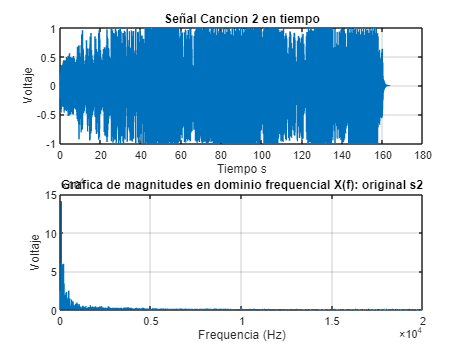


% grafica de la señal original 2 en dominio frequencial 
figure(2)
subplot(2,1,2)
dom_frequencialB = ((0:length(audio2)-1)*(fs/length(audio2)));
plot(dom_frequencialB, abs(fft_signal2))
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial X(f): original s2')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,1)
plot(periodo2, audio2)
grid on
xlabel('Tiempo s')
ylabel('Voltaje')
title('Señal Cancion 2 en tiempo')

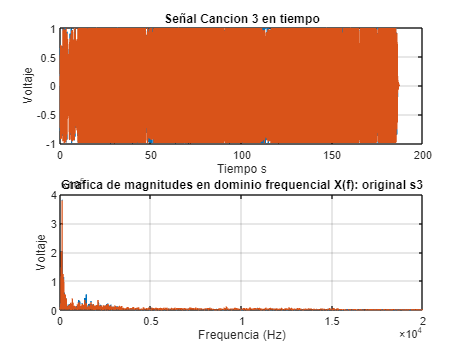

% grafica de la señal original 3 en dominio frequencial 
figure(3)
subplot(2,1,2)
dom_frequencialC = (0:length(audio3)-1)*(fs/length(audio3));
plot(dom_frequencialC, abs(fft_signal3))
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial X(f): original s3')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,1)
plot(periodo3, audio3)
grid on
xlabel('Tiempo s')
ylabel('Voltaje')
title('Señal Cancion 3 en tiempo')

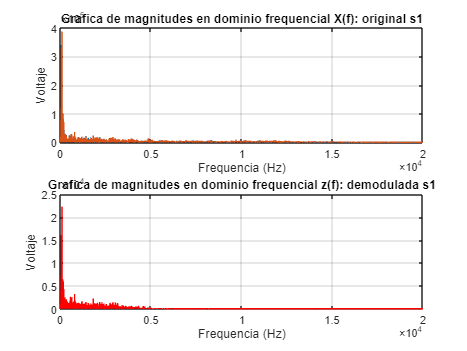


%2) Definir señalel portadoras
% definición de señal poradora ... freq = 530khz
portadora_freq1 = 580000; % frequencia de portadora en Hz
t_portadora = 0:1/fs:duracion1; % Dominio en el tiempo
portadora = cos(2*pi*portadora_freq1*t_portadora);

% definición de señal poradora ... freq = 530khz
portadora_freq2 = 800000; % frequencia de portadora en Hz
t2_portadora = 0:1/fs:duracion2; % Dominio en el tiempo
portadora2 = cos(2*pi*portadora_freq2*t2_portadora);

% definición de señal poradora ... freq = 530khz
portadora_freq3 = 950000; % frequencia de portadora en Hz
t3_portadora = 0:1/fs:duracion3; % Dominio en el tiempo
portadora3 = cos(2*pi*portadora_freq3*t3_portadora);

%3) Realizar multiplicación 

% % Normalización de la señal original: audio
 %audio = audio / max(abs(audio));

% realizar multiplicación entre:
% (audio) -> (portadora) 

modulada = audio .* portadora';
modulada2 = audio2 .* portadora2';
modulada3 = audio3 .* portadora3';

a = modulada(1:3000000,1); 
b = modulada2(1:3000000,1); 
c = modulada3(1:3000000,1); 

modulated_complete = a + b + c; 

% Normalize the modulated signal
modulated_complete = modulated_complete / max(abs(modulated_complete));


% guardar señal modulada en nueva variable
%audiowrite('fft_modulated.wav', modulated_complete, fs);

% grafica de la señal modulada en dominio frequencial 
% señal modulada
%[modulada, fs] = audioread('fft_modulated.wav'); 

% fft_modulada = fft(modulated_complete); 
% 
% muestreo = portadora_freq3*2; 
% %N = muestreo * 2; %Número de muestras
% 
% fft_modulada = abs(fft_modulada);
% fft_modulada = fft_modulada(1:N/2+1);
% fft_modulada(2:end-1) = 2*fft_modulada(2:end-1);
% dom_frequencialmod = muestreo*(0:(N/2))/N;%(0:length(modulated_complete)-1)*(multiplyer/length(modulated_complete));
% figure(4)
% plot(dom_frequencialmod, fft_modulada)
% xlabel('Frequencia (Hz)')
% ylabel('Voltaje')
% title('Grafica de magnitudes en dominio frequencial y(f): modulada')
% grid on

%4) Proceso: DEMODULACIÓN
duracion = (length(modulated_complete)-1) / fs; 

% definición de señal poradora ... freq = 530khz
portadora_freq1 = 580000; % frequencia de portadora en Hz
t = 0:1/fs:duracion; % Dominio en el tiempo
portadora = cos(2*pi*portadora_freq1*t);

% definición de señal poradora ... freq = 530khz
portadora_freq2 = 800000; % frequencia de portadora en Hz
t2 = 0:1/fs:duracion; % Dominio en el tiempo
portadora2 = cos(2*pi*portadora_freq2*t2);

% definición de señal poradora ... freq = 530khz
portadora_freq3 = 950000; % frequencia de portadora en Hz
t3 = 0:1/fs:duracion; % Dominio en el tiempo
portadora3 = cos(2*pi*portadora_freq3*t3);

% demodulación
demodulada1 = modulated_complete .* portadora';
demodulada2 = modulated_complete .* portadora2';
demodulada3 = modulated_complete .* portadora3';

% s1 --------------------------------------------------
% low pass filter
cutoff_freq =  2500; % Cutoff frequency in Hz (set to the highest audible frequency, 20 kHz)
demodulada_filtered1 = lowpass(demodulada1, cutoff_freq, fs);

% s2 --------------------------------------------------
% low pass filter
cutoff_freq =  4600; % Cutoff frequency in Hz (set to the highest audible frequency, 20 kHz)
demodulada_filtered2 = lowpass(demodulada2, cutoff_freq, fs);

% s3 --------------------------------------------------
% low pass filter
cutoff_freq =  3500; % Cutoff frequency in Hz (set to the highest audible frequency, 20 kHz)
demodulada_filtered3 = lowpass(demodulada3, cutoff_freq, fs3);

% guardar señal modulada en nueva variable
audiowrite('demod_s1.wav', demodulada_filtered1, fs);
% guardar señal modulada en nueva variable
audiowrite('demod_s2.wav', demodulada_filtered2, fs2);
% guardar señal modulada en nueva variable
audiowrite('demod_s3.wav', demodulada_filtered3, fs3);

% grafica de la señal demodulada en dominio frequencial 

% señal demodulada 1 en freq y temporal
[demod_s1, fs1] = audioread('demod_s1.wav'); 
fft_demod1 = fft(demod_s1); 
dom_frequencial = (0:length(demod_s1)-1)*(fs1/length(demod_s1));

figure(5)
subplot(2,1,2)
plot(dom_frequencial, abs(fft_demod1), 'r')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial z(f): demodulada s1')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,1)
dominio1 = (0:length(fft_signal)-1)*(fs/length(fft_signal));
plot(dominio1, abs(fft_signal))
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial X(f): original s1')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

a = audio(1:length(demod_s1), 1);
corrcoef(a, demod_s1)

ans =     1.0000    0.9529
    0.9529    1.0000


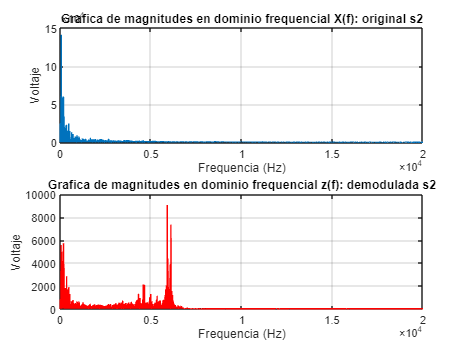



% señal demodulada 2 en freq y temporal
[demod_s2, fs2] = audioread('demod_s2.wav'); 
fft_demod2 = fft(demod_s2); 

dom_frequencial2 = (0:length(demod_s2)-1)*(fs/length(demod_s2));
figure(6)
subplot(2,1,2)
plot(dom_frequencial2, abs(fft_demod2), 'r')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial z(f): demodulada s2')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,1)
dominio2 = (0:length(fft_signal2)-1)*(fs/length(fft_signal2));
plot(dominio2, abs(fft_signal2))
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial X(f): original s2')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

b = audio2(1:length(demod_s2), 1);
corrcoef(b, demod_s2)

ans =     1.0000    0.8309
    0.8309    1.0000


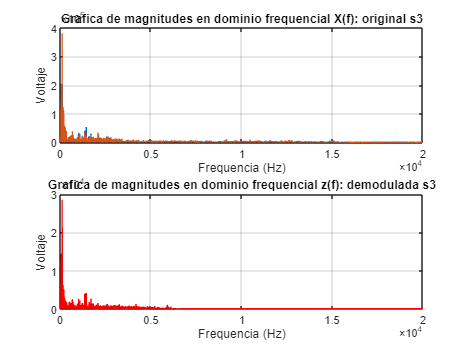



% señal demodulada 3 en freq y temporal
[demod_s3, fs] = audioread('demod_s3.wav'); 
fft_demod3 = fft(demod_s3); 

dom_frequencial3 = (0:length(demod_s3)-1)*(fs/length(demod_s3));
figure(7)
subplot(2,1,2)
plot(dom_frequencial3, abs(fft_demod3), 'r')
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial z(f): demodulada s3')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

subplot(2,1,1)
dominio3 = (0:length(fft_signal3)-1)*(fs/length(fft_signal3));
plot(dominio3, abs(fft_signal3))
xlabel('Frequencia (Hz)')
ylabel('Voltaje')
title('Grafica de magnitudes en dominio frequencial X(f): original s3')
grid on
xlim([0 20000])  % Limits set to 0 Hz to 20,000 Hz

c = audio3(1:length(demod_s3), 1);
corrcoef(c, demod_s3)

ans =     1.0000    0.9629
    0.9629    1.0000
